## illustrating 1/f and DFT

### Part 1: 1/f and averaging across segments

Start by making a discrete time vector... 

clear
time = 0.001:0.001:1; % one second of discrete time
faxis = 0:500; % frequency axis goes from 0 to nyquist in steps of 1

... now make white noise (stochastic) segments, the same noise to be used for all future simulations

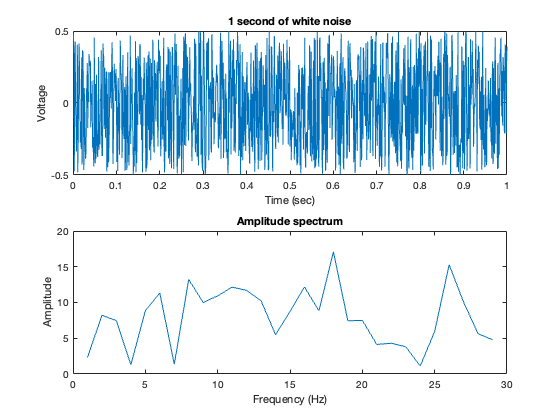

whitesig = rand(50,1000)-.5; % zero centered white noise

for trial = 1:50
    subplot(2,1,1), plot(time, whitesig(trial, :)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of white noise')
    fftspec = fft(whitesig(trial, :)'); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)

end

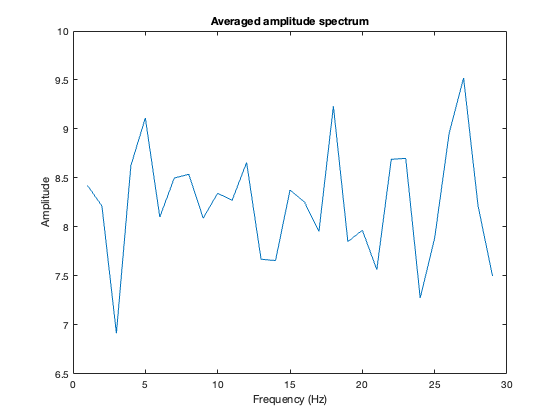


figure
plot(mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

now we do it again with the cumulative sum of the white noise, which results in brownian noise

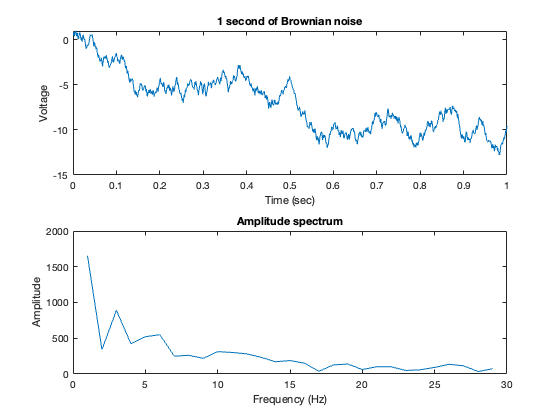

for trial = 1:50

    brownsig(trial,:) = cumsum(whitesig(trial, :));
    subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)

end

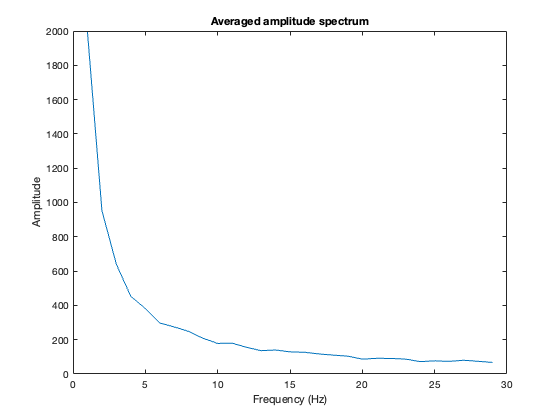


figure
plot(mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

now we add a variable alpha oscillation to each trial

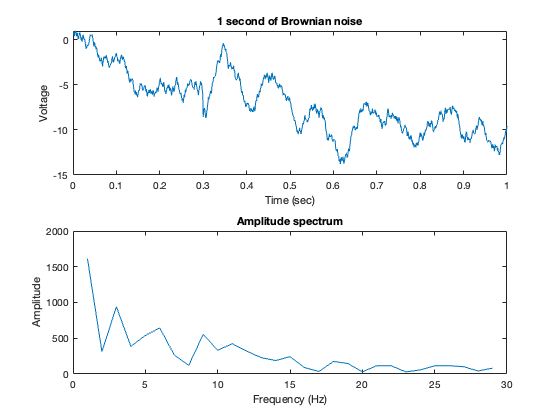


for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sin(2*pi*time*(8+rand(1,1).*3)).*3;
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)

end

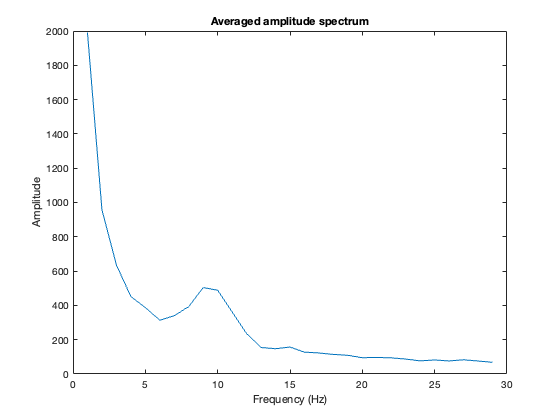


figure
plot(mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

Same, but we do 10 runs and look at the variability across runs after averaging 50 trials 

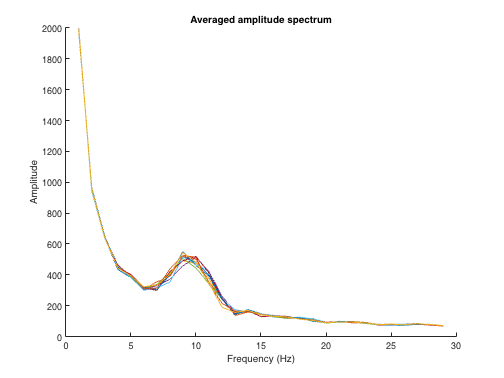

figure, hold on

for run = 1:10
  for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sin(2*pi*time*(8+rand(1,1).*3)).*3;
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspecsine(trial, :) = abs(fftspec); % save it for later
  end

  plot(mean((sumspecsine(:, 2:30))))
  xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum with Sine-shaped alpha')
end
hold off

Same, but we do 10 runs with SAWTOOTH instead of sine-shaped akpha and look at the variability across runs after averaging 50 trials 

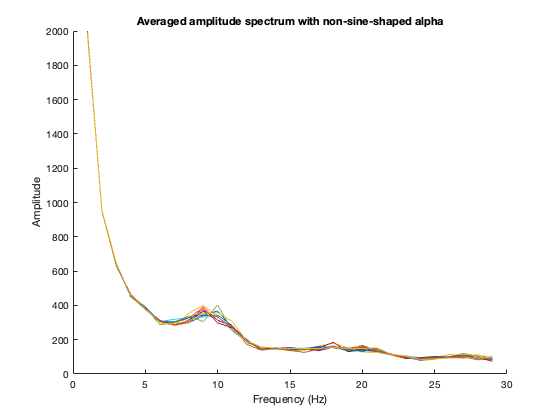

figure, hold on

for run = 1:10
  for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sawtooth(2*pi*time*(8+rand(1,1).*3)).*3;
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
  end

  plot(mean((sumspec(:, 2:30))))
  xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum with non-sine-shaped alpha')
end
hold off

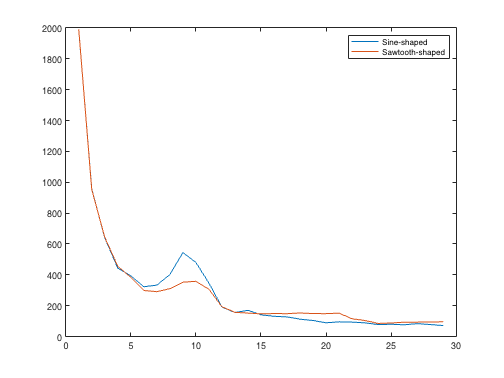


figure
  plot(mean((sumspecsine(:, 2:30))))
  hold on 
  plot(mean((sumspec(:, 2:30))))
  legend('Sine-shaped', 'Sawtooth-shaped')